# Correlación lineal

## Coeficiente de correlación de Pearson

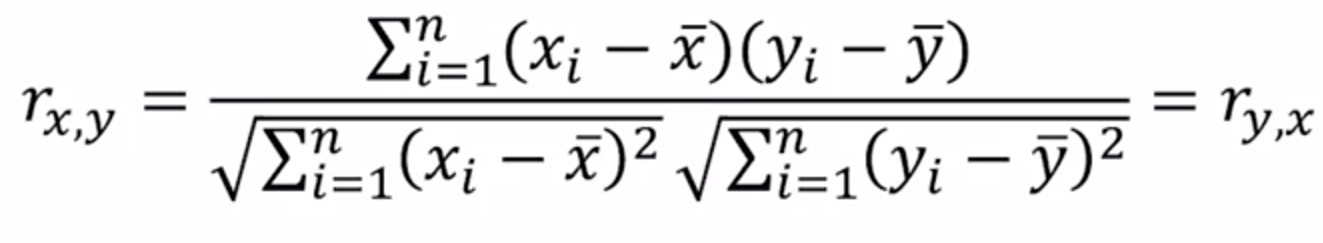

Para comparar dos variables, es necesario utilizar una medida que pueda describirnos que tan relacionadas estan dichas variables. Una de ellas es el coeficiente de correlación

## Dataset

Para este ejemplo utilizaremos el dataset de pacientes y su presión arterial

load patients
data = table(Age,Gender,Height,Weight,Smoker,SelfAssessedHealthStatus,Systolic,Diastolic);
clearvars -except data



## Ejemplo correlación

Consideremos dos variables que esperamos tenga una alta semejanza, como la altura vs peso, la función `corr` nos permite obtener el coeficiente de correlación entre 2 conjuntos de datos.

el rango del coeficiente de correlación es un valor entre -1 y 1

r1_xy = corr(data.Height,data.Weight)

r1_xy = 0.6960

## Interpretación del coeficiente de correlación

### Correlación positiva


$$r_{x,y} >0$$


Conforme incrementa la variable X, incrementa la variable Y

### Correlación negativa


$$r_{x,y} <0$$


conforme incrementa la variable X, disminuye la variable Y

La correlación positiva entre Height vs Weight es evidente en la misma gráfica

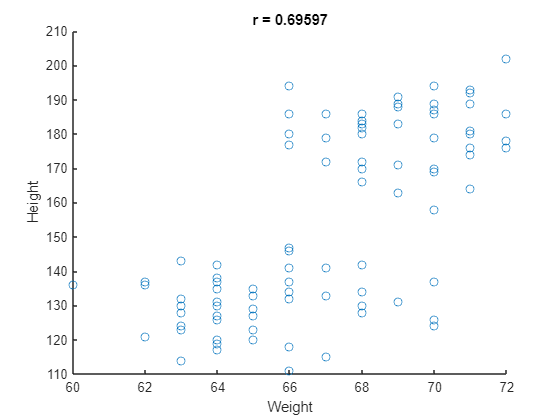

scatter(data.Height,data.Weight)
xlabel('Weight')
ylabel('Height')
title("r = "+num2str(r1_xy))

### Magnitud

Para este ejemplo ahora examinemos dos variables que sabemos son poco semejantes en su comportamiento en adultos, como la altura y edad

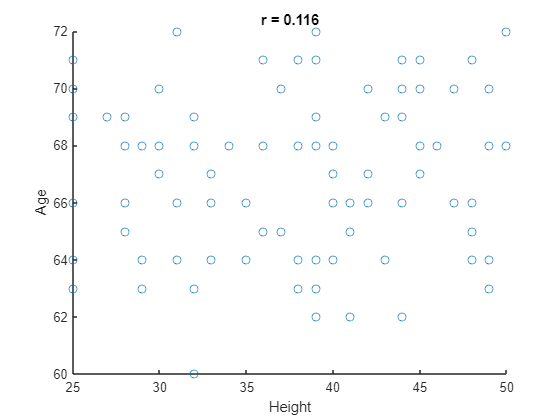

r2_xy = corr(data.Age,data.Height);
scatter(data.Age,data.Height)
xlabel('Height')
ylabel('Age')
title("r = "+num2str(r2_xy))

si bien el signo indica una correlación positiva, no es evidente la semejanza en comportamiento de las variables

La magnitud indica la "fuerza" de la correlación (correlation strength) 


$$r_{x,y} \approx -1$$


Valores cercanos a -1 indican fuerte correlación negativa, los valores estarán cercanos a una recta con pendiente negativa


$$r_{x,y} \approx 1$$


Valores cercanos a 1 indican fuerte correlación positiva, los valores estarán cercanos a una recta con pendiente positiva


$$r_{x,y} \approx 0$$


Valores cercanos a 0 indican debil correlación o ausencia de ella

## Consideraciones adicionales

El coeficiente de correlación no está asociado al valor de la pendiente de la relación lineal entre 2 variables, solo que tan cerca estan los valores de la línea

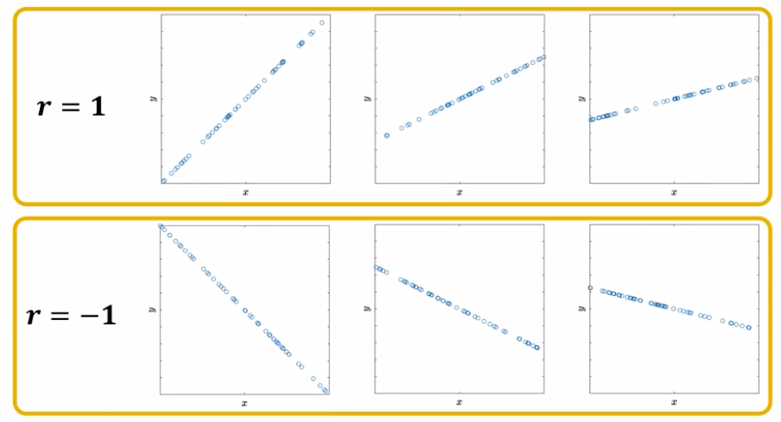

Se puede obtener un mismo coeficiente para relaciones lineales con diferente pendiente

No es de utilidad para describir relaciones no lineales

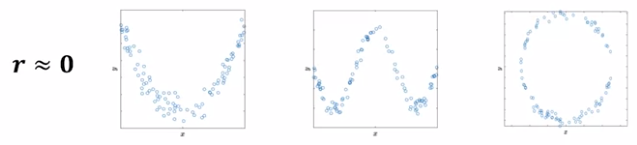

## Calcular multiples correlaciones

Es posible calcular la correlación de una variable en comparación con varias en un mismo comando

corr(data.Age,[data.Systolic,data.Diastolic])

ans =     0.1341    0.0806


% Las gráficas coinciden con el valor del coeficiente de correlación?

% Puede calcularse con variables tipo logical
corr(data.Smoker,[data.Systolic,data.Diastolic])

ans =     0.7063    0.7234



% o calcular con una variable categorial o texto
corr(data.Gender == "Female",[data.Systolic,data.Diastolic])

ans =    -0.1600   -0.2175
